D = csvread("output_phi_log.txt");

totalSteps = size(D,1);
phi0 = D(13:totalSteps,1);
phi1 = D(13:totalSteps,3);
t = (13:totalSteps)';

max_phiu = 40;
min_phiu = 1;

max_phic = 4.3;
min_phic = 1.62;

a = 0.7;
b = 1;

gammaMax = a/b * max_phiu/min_phic * 1000

gammaMax = 1.7284e+04

gammaMin = a/b * min_phiu/max_phic * 1000

gammaMin = 162.7907


len_t = length(t);

expell_0 = find(D(13:totalSteps,2) == 1) - 1;
expell_1 = find(D(13:totalSteps,4) == 1) - 1;
de_0 = expell_0(2 : size(expell_0,1) ) - expell_0(1 : size(expell_0,1) - 1);
de_1 = expell_1(2 : size(expell_1,1) ) - expell_1(1 : size(expell_1,1) - 1);

de_0;
de_1;

[min_0, max_0] = bounds(de_0)

min_0 = 588

max_0 = 945


[min_1, max_1] = bounds(de_1)

min_1 = 224

max_1 = 766

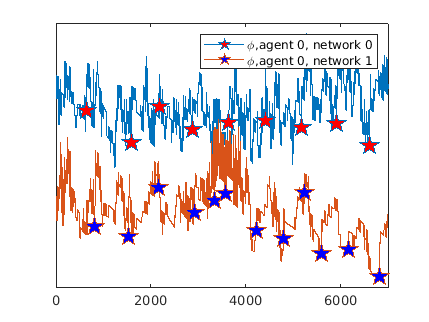



plot(t,phi0 - 15,'-p','MarkerIndices',expell_0,...
    'MarkerFaceColor','red',...
    'MarkerSize',15)
xlim([0,7001])
hold on
plot(t,phi1,'-p','MarkerIndices',expell_1,...
    'MarkerFaceColor','blue',...
    'MarkerSize',15)
xlim([0,7001])

set(gca, 'YTick', [])

legend("\phi,agent 0, network 0", "\phi,agent 0, network 1")



hold off